# Beyond Raman Nath Regime for X beam and Xbar beam

## Initialization



units % load some common physical constants
m_Li6mol = 2*m_Li6;
aLi_12 = 982*a0;
add_Li = aLi_12*0.6;

totalODTpower = 22.5;
EndODTpower = 22.5;

omegax = 81*pi*2*sqrt(EndODTpower/totalODTpower); % trap frequencies 
omegay = 3040*pi*2*sqrt(EndODTpower/totalODTpower);
omegaz = 3040*pi*2*sqrt(EndODTpower/totalODTpower);

% scale parameters
tscale = 1/(omegax); % time scale
rscale = sqrt(hbar/m_Li6mol/omegax); % spatial scale

% Lattice parameters defination
Wavelength = 1064*10^-9;

D = Wavelength/2; % Lattice period 0.532 micons
Erecoil = hbar^2*(pi/D)^2/(2*m_Li6mol); % recoil energy 


LatticePow = 5; % optical power in unit of Watt
LatticeRate = 2.3885; % optical power is 2.3885mico-K/W

LatticePotential = LatticePow.*LatticeRate.*kb.*10^-6 / Erecoil;
% LatticePotential = 50; % lattice depth in unit of recoil energy
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Theta = pi*0.99; % symmetry phase
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
V = @(X,Y,Z) 0.5*(X.^2 ); % function representing the external potential (must have 3 arguments)


ymax = 25*D/rscale; %  grid boundaries [-xmax,xmax]
xmax = 800*D/rscale; %  grid boundaries [-xmax,xmax]
Nx = 16000; % number of grid points for coordinate grid
Ny = 500;
try
    x = gpuArray.linspace(-xmax,xmax,Nx);
    grid = grid1d(x);
catch
    grid = grid1d(xmax,Nx); % create a two-dimensional NxN grid object
end

task = GPEtask(grid,V); % initialize the GPE solver
task.Ntotal = 3000; % wave function normalization (total number of atoms)

task.whisper = false;
task.Xscale = rscale;
task.Tscale = tscale;
task.LatticeConstant = D;



## Stationary state calculation

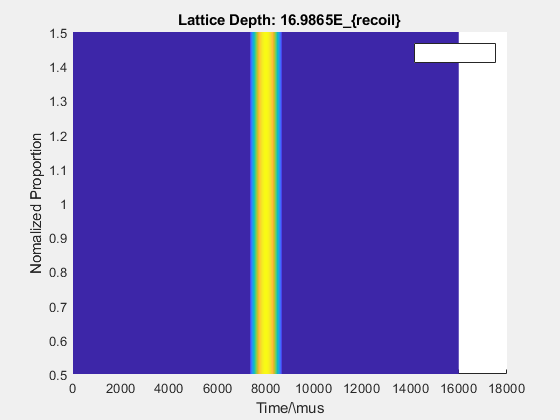


% phi = task.groundstate_itp(tstep,acc,'tf'); % phi will contain calculated stationary state
[phi,mu,R] = task.groundstate_tf_harmonic(add_Li,omegax,omegay,omegaz);

% Plot the initial state
imagesc(abs(phi).^2)


% task.g = 4*pi*add_Li/rscale/sqrt(2*pi/sqrt(omegaz*omegay)*omegax); % nonlinear interaction constant
task.g = 16*add_Li/(3*rscale* R(1).^2); % nonlinear interaction constant
task.g = 0;


%% switch on lattice for Deltat
Deltat = 20*10^-6/tscale; % total duration for simulation; (20 mico-seconds)
tstep = 3*10^-9/tscale; % time step for calculation; (20 ns)
steps_int = 10;  % number of intenal steps. (should be larger than 10 task.n_recalc)

task.init_state = phi;
task.show_image = 0; % show the solution on every precessing step


NmaxP = 2; % maximum mode of momentum to be analyzed

% function representing the external potential (must have 3 arguments)
Vlattice = @(X,Y,Z) LatticePotential*Erecoil/(hbar*omegax)...
    *(cos((pi/D)*X*rscale).^2  + cos((pi/D)*X*rscale + Theta/2).^2  ); 
task.UpdatePotential(Vlattice);
task.history.MomentumDensity = [];
task.user_callback = @(x)task.FFTanalysis(false,NmaxP);
steps_ext = task.current_iter + Deltat/tstep/steps_int;


##  Raman-Nath regime?

For Raman-Nath regime


$$t_{\max } \frac{\sqrt{E_r U_0 }}{\hbar }<1$$


Deltat*tscale * sqrt(LatticePotential)*Erecoil/hbar

ans = 7.5872

## start simulation


task.solve_split(tstep,steps_int,steps_ext); % run the calculation

## momentum modes distribution

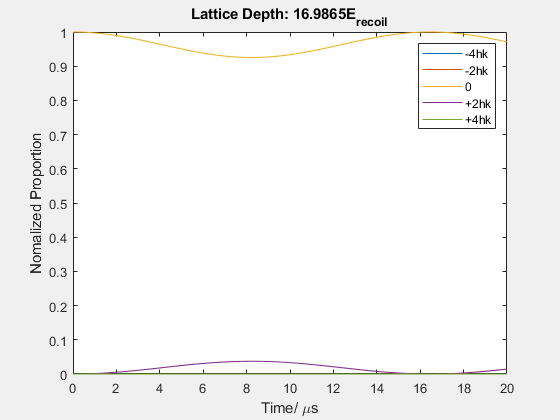


trange = (0:steps_ext)*tstep*steps_int*tscale;
% MomentumDensity = Get_momentumDesity_2D( ...
%     task.history.MomentumDensity,1:NmaxP*2+1,NmaxP+1);
MomentumDensity = task.history.MomentumDensity;
MomentumDensity = MomentumDensity./max(MomentumDensity(:));
plot(trange*10^6, MomentumDensity(:,NmaxP-1:NmaxP+3)')
xlabel('Time/ \mus')
ylabel("Nomalized Proportion")
title(['Lattice Depth: ',num2str(LatticePotential),'E_{recoil}'])
legend('-4hk','-2hk','0','+2hk','+4hk')

task.saveTask('Theta',num2str(Theta/pi))

ans = 'Successfully saved in ./Data/D532_1D_Tstep3_Tnow19.98Theta0.99'

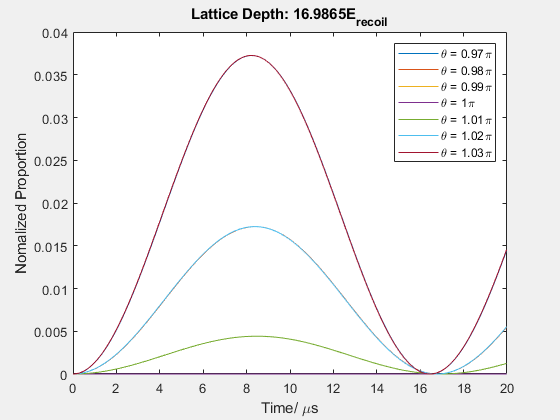

for i = 0.97:0.01:1.03
FileName = ['./Data/D532_1D_Tstep3_Tnow19.98Theta',num2str(i)];
load(FileName,'-mat')

task = obj;
DisplayMode = 2;


MomentumDensity = task.history.MomentumDensity;
MomentumDensity = MomentumDensity./max(MomentumDensity(:));
trange = (0:task.history.steps_ext)*task.history.tstep*task.history.steps_int*task.Tscale;



plot(trange*10^6, MomentumDensity(:,DisplayMode)' ...
    ,'DisplayName',['\theta = ',num2str(i),'\pi'])
hold on
end
xlabel('Pulse Duration/ \mus')
ylabel("Nomalized Proportion")
title(['Lattice Depth: ',num2str(LatticePotential),'E_{recoil}'])
hold off
legend